file = load('./Data_assignment_4/ex7M1.mat');
speech = file.speech2_10k;

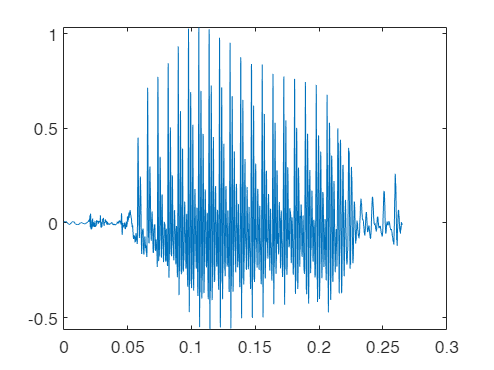

Fs = 10000;
range = (1:length(speech))/Fs;
plot(range, speech);

window = triang(0.03*Fs);

w_speech = zeros(1, length(window)*ceil(length(speech)/length(window)));
w_speech(1:length(speech)) = speech;
speech = w_speech;
num_windows = ceil(length(speech)/length(window));

num_windows = 9

windowed_speech = zeros(ceil(length(speech)/length(window)), length(window));
for i=0:num_windows-1
%     disp(i*length(window)+1)
%     disp((i+1)*length(window))
    windowed_speech(i+1, :) = speech(i*length(window)+1:(i+1)*length(window));
end

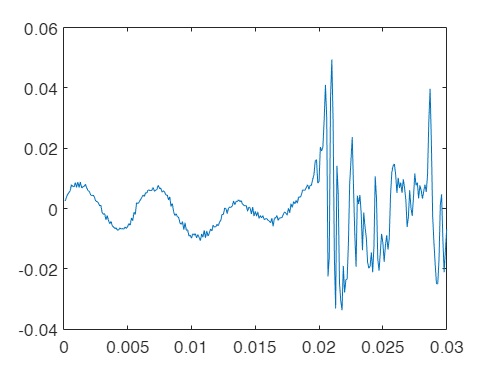

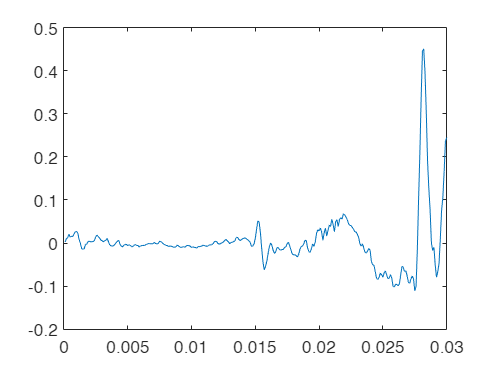

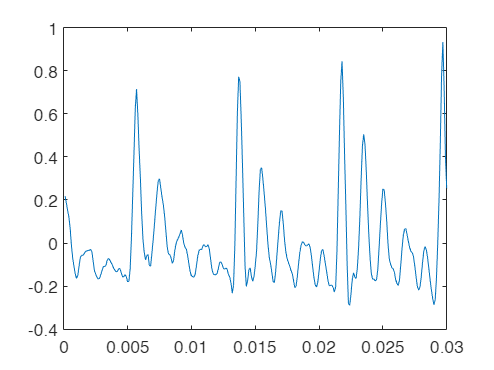

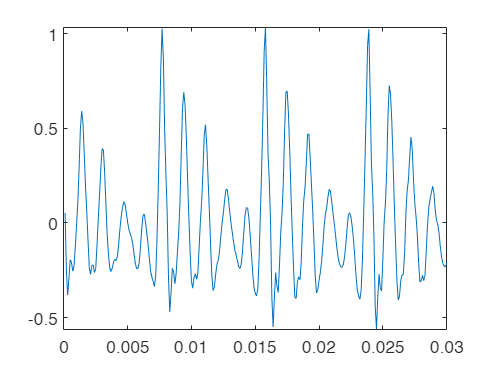

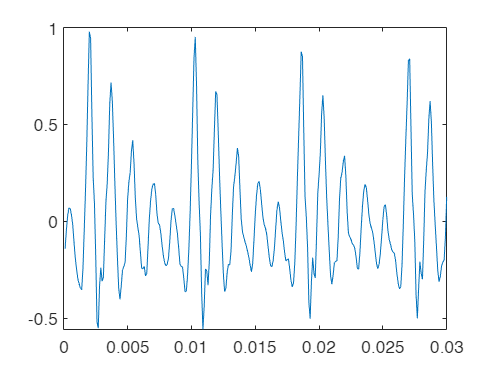

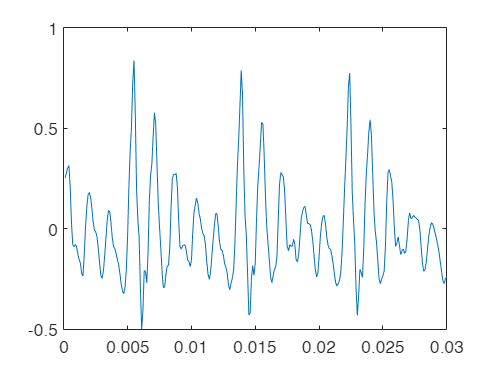

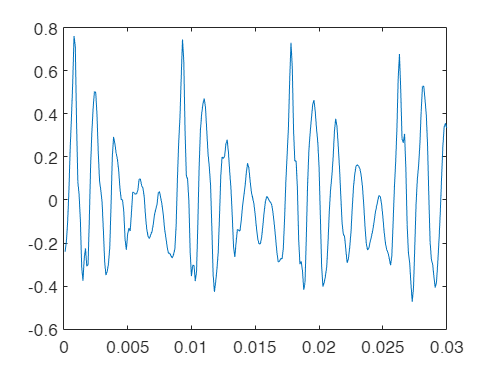

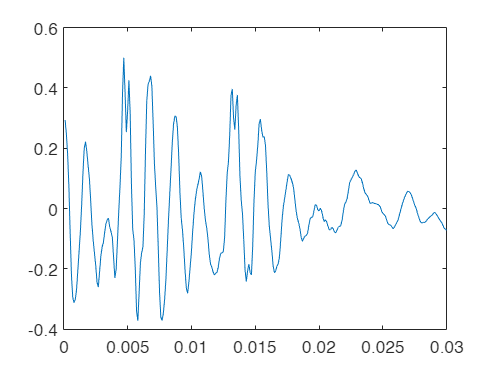

range_win = (1:length(window))/Fs;
for i=1:num_windows
    figure;
    plot(range_win, windowed_speech(i, :));
end